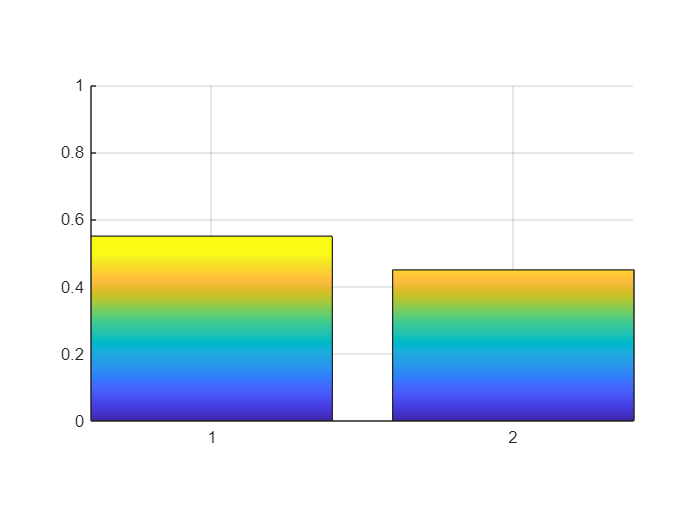


%% SPLITTER POWER FRACTION 
close all;
clearvars;
kL =0.234;
Input(1) = 1 ;
Input(2) = 0 ;

Tc_matrix = [ cos(kL*pi)   ,  -1i*sin(kL*pi); 
             -1i*sin(kL*pi),   cos(kL*pi)  ];

Output = Tc_matrix*(Input)';

I_F_1 = (abs(Output(1))^2)/(abs(Input(1)^2) + abs(Input(2))^2);
I_F_2 = (abs(Output(2))^2)/(abs(Input(1)^2) + abs(Input(2))^2);
Intensity_fraction_1 = sprintf('%.3f%%',I_F_1*100);
Intensity_fraction_2 = sprintf('%.3f%%',I_F_2*100);

y = [I_F_1 I_F_2];
b = bar3(y);
colormap default
b.FaceColor = "interp";
for a = 1:length(b)
    b(a).CData = b(a).ZData;
end
zlim([0 1])
clim([0 0.5])
view(-90,0)

disp("Intensity output BAR : " + Intensity_fraction_1 + "        Intensity output CROSS : " + Intensity_fraction_2)

Intensity output BAR : 55.018%        Intensity output CROSS : 44.982%
